# Cameras

We render the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

This script  illustrates how to set the focal distance, and it reveals the depth of field for this double Gauss lens.

## Set up ISETCam

Also, make sure we have docker running.

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the PBRT scene

thisR = piRecipeDefault('scene name', 'bmw-m6');

/home/dad/WS3/iset3d/data/scenes/bmw-m6/bmw-m6.pbrt
Read 28 materials and 0 textures..


thisR.set('spatial resolution', 1024);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

The distance that will be in focus

%thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

%thisR.set('from',  [0, 0.5, -0.5]); %[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene surpise me.

%piCameraRotate(thisR, 'x rot',-10);

Summarize the recipe information.  There is a lot for this scene.  But you can handle it.

thisR.summarize;


File information
-----------
Input:  /home/dad/WS3/iset3d/data/scenes/bmw-m6/bmw-m6.pbrt
Output: /home/dad/WS3/iset3d/local/bmw-m6/bmw-m6.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 8

Camera parameters
-----------
Sub type: omni
Lens file name:   /home/dad/WS3/isetcam/data/lens/dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	10.00
Exposure time (s):	1.000000
Field of view (deg):	28.940553

Film parameters
-----------
subtype: gbuffer
x,y resolution: 1024 1024 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	-11.000 0.800 5.000
to:	-2.000 -0.500 0.000
up:	0.000 1.000 0.000
object distance: 10.377 (m)
                                       material            positions (m)          sizes (m)   
                                 ____________________    __________________    _______________

    000005ID_001_mesh_000

## Write and render

User name: dad
Rendered time 372.76

------------------
Container command: docker --context default exec -it  pbrt-gpu-dad8861 sh -c "cd /iset/iset3d-v4/local/bmw-m6 && pbrt --outfile renderings/bmw-m6.exr bmw-m6.pbrt"
PBRT command: pbrt --outfile renderings/bmw-m6.exr bmw-m6.pbrt

------------------

Output file:  renderings/bmw-m6.exr
*** Rendering time (bmw-m6) was 373.2 sec ***



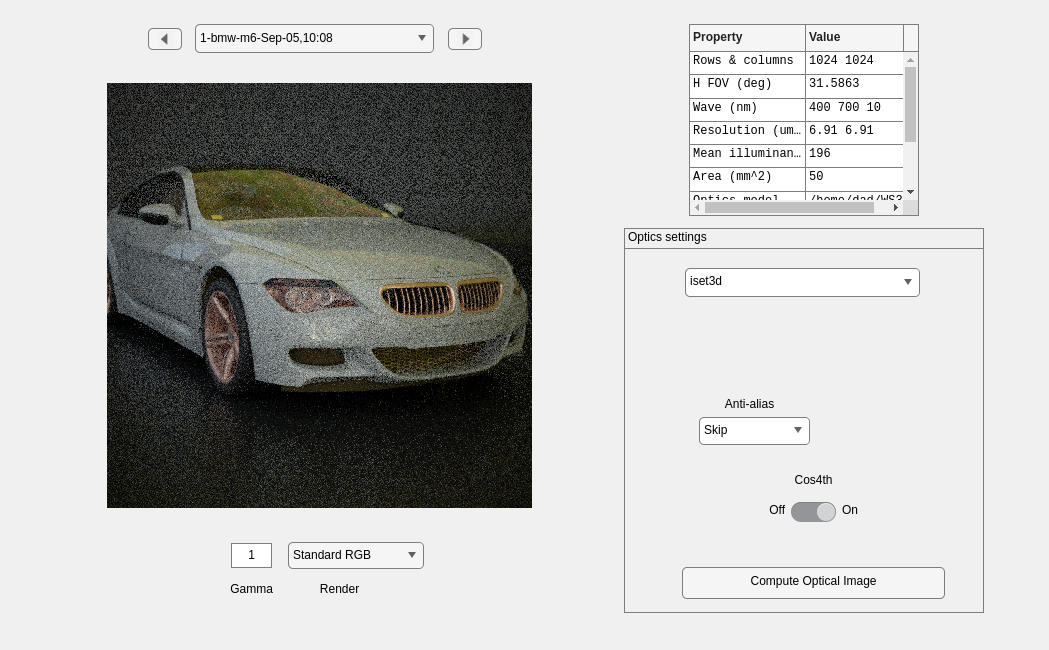

oi=piWRS(thisR,'render type','radiance'); 



%sensor = sensorCompute(sensor,oi);
%sensorWindow(sensor);

## Change the focus distance to 0.4m

%thisR.set('focus distance',0.4);
%oi=piWRS(thisR,'render type','radiance');

sensor = sensorCreate('light field', oi); %('bayer (grgr)');

SensorCreate() ...
lightfield
SensorCreate() ...
default


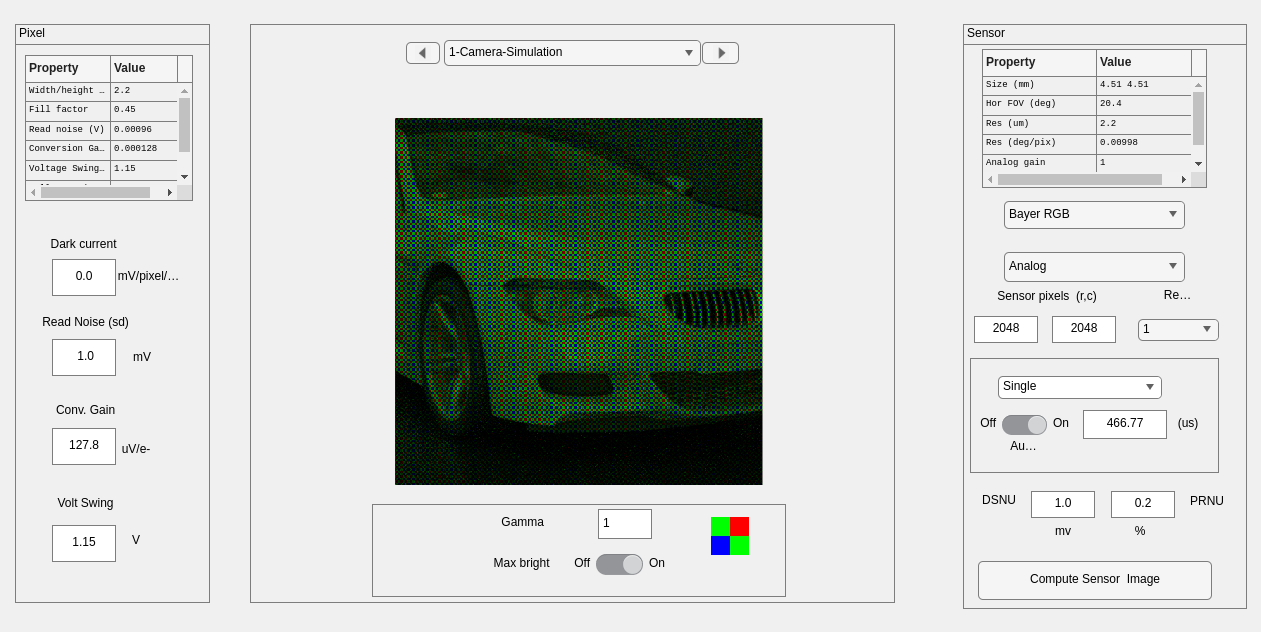

%sensor = sensorCreate;

% We set the sensor properties using *sensorSet* and *sensorGet*
% routines.
%
% Just as the optical irradiance gives a special status to the
% optics, the sensor gives a special status to the pixel.  In
% this section we define the key pixel and sensor properties, and
% we then put the sensor and pixel back together.

% To get the pixel structure from the sensor we use:
pixel =  sensorGet(sensor,'pixel');

% Here are some of the key pixel properties
voltageSwing   = 1.15;  % Volts
wellCapacity   = 9000;  % Electrons
conversiongain = voltageSwing/wellCapacity;
fillfactor     = 0.45;       % A fraction of the pixel area
pixelSize      = 2.2*1e-6;   % Meters
darkvoltage    = 1e-005;     % Volts/sec
readnoise      = 0.00096;    % Volts

% We set the pixel properties here.
sensor = sensorSet(sensor,'pixel size same fill factor',[pixelSize pixelSize]);
sensor = sensorSet(sensor,'pixel conversion gain', conversiongain);
sensor = sensorSet(sensor,'pixel voltage swing',voltageSwing);
sensor = sensorSet(sensor,'pixel dark voltage',darkvoltage) ;
sensor = sensorSet(sensor,'pixel read noise volts',readnoise);

%  Now we set some general sensor properties
dsnu =  0.0010;           % Volts (dark signal non-uniformity)
prnu = 0.2218;            % Percent (ranging between 0 and 100) photodetector response non-uniformity
analogGain   = 1;         % Used to adjust ISO speed
analogOffset = 0;         % Used to account for sensor black level
rows = 2048;               % number of pixels in a row
cols = 2048;               % number of pixels in a column

% Set sensor properties
sensor = sensorSet(sensor,'auto exposure',true);
% N.B. You could set the exposure duration explicitly using
% sensor = sensorSet(sensor,'exp time',0.030);

% Some other
sensor = sensorSet(sensor,'rows',rows);
sensor = sensorSet(sensor,'cols',cols);
sensor = sensorSet(sensor,'dsnu level',dsnu);
sensor = sensorSet(sensor,'prnu level',prnu);
sensor = sensorSet(sensor,'analog Gain',analogGain);
sensor = sensorSet(sensor,'analog Offset',analogOffset);

% Adjust the pixel fill factor
sensor = pixelCenterFillPD(sensor,fillfactor);

% It is also possible to replace the spectral quantum efficiency curves of
% the sensor with those from a calibrated camera.  We include the
% calibration data from a very nice Nikon D100 camera as part of ISET.
% To load those data we first determine the wavelength samples for this sensor.
wave = sensorGet(sensor,'wave');

% Then we load the calibration data and attach them to the sensor structure
fullFileName = fullfile(isetRootPath,'data','sensor','colorfilters','nikon','NikonD100.mat');
[data,filterNames] = ieReadColorFilter(wave,fullFileName);
sensor = sensorSet(sensor,'filter spectra',data);
sensor = sensorSet(sensor,'filter names',filterNames);
sensor = sensorSet(sensor,'Name','Camera-Simulation');


sensor = sensorCompute(sensor, oi);
sensorWindow(sensor);




%Image Processor

ip = ipCreate;

% The routines for setting and getting image processing
% parameters are ipGet and ipSet.
%
ip = ipSet(ip,'name','Unbalanced');
ip = ipSet(ip,'scale display',1);

% The default properties use bilinear demosaicking, no color
% conversion or balancing.  The sensor RGB values are simply set
% to the display RGB values.
ip = ipCompute(ip,sensor);

% As in the other cases, we can bring up a window to view the
% processed data, this time a full RGB image.
ieAddObject(ip); ipWindow

ans =   ipWindow_App with properties:

                        figure1: [1×1 Figure]
                       menuFile: [1×1 Menu]
                   menuFileLoad: [1×1 Menu]
           menuFileSaveProcData: [1×1 Menu]
              menuFileLoadImage: [1×1 Menu]
                   menuFileSave: [1×1 Menu]
                menuFileRefresh: [1×1 Menu]
                  menuFileClose: [1×1 Menu]
                       menuEdit: [1×1 Menu]
                   menuEditName: [1×1 Menu]
                 menuEditCreate: [1×1 Menu]
              menuEditCopyImage: [1×1 Menu]
                 menuEditDelete: [1×1 Menu]
             menuEditDeleteSome: [1×1 Menu]
                 menuImageWhite: [1×1 Menu]
             menuEditResetWhite: [1×1 Menu]
             menuScaleChooseMax: [1×1 Menu]
               menuScaleDisplay: [1×1 Menu]
               menuEditFontSize: [1×1 Menu]
           menuEditClearMessage: [1×1 Menu]
          

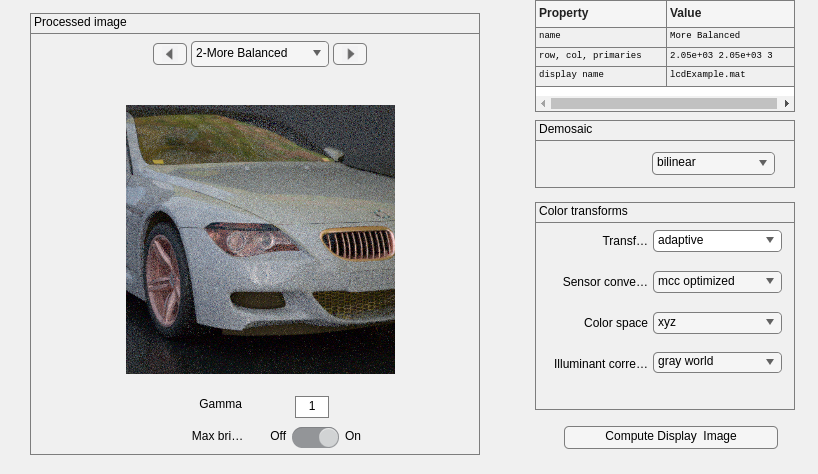

ans =   ipWindow_App with properties:

                        figure1: [1×1 Figure]
                       menuFile: [1×1 Menu]
                   menuFileLoad: [1×1 Menu]
           menuFileSaveProcData: [1×1 Menu]
              menuFileLoadImage: [1×1 Menu]
                   menuFileSave: [1×1 Menu]
                menuFileRefresh: [1×1 Menu]
                  menuFileClose: [1×1 Menu]
                       menuEdit: [1×1 Menu]
                   menuEditName: [1×1 Menu]
                 menuEditCreate: [1×1 Menu]
              menuEditCopyImage: [1×1 Menu]
                 menuEditDelete: [1×1 Menu]
             menuEditDeleteSome: [1×1 Menu]
                 menuImageWhite: [1×1 Menu]
             menuEditResetWhite: [1×1 Menu]
             menuScaleChooseMax: [1×1 Menu]
               menuScaleDisplay: [1×1 Menu]
               menuEditFontSize: [1×1 Menu]
           menuEditClearMessage: [1×1 Menu]
          


%% You can experiment by changing the processing parameters

% For example
ip2 = ipSet(ip,'name','More Balanced');
ip2 = ipSet(ip2,'internalCS','XYZ');
ip2 = ipSet(ip2,'conversion method sensor','MCC Optimized');
ip2 = ipSet(ip2,'correction method illuminant','Gray World');

% With these parameters, the colors will appear to be more accurate
ip2 = ipCompute(ip2,sensor);

ipWindow(ip2)


% Again, this window offers the opportunity to perform many
% parameter changes and to evaluate certain metric properties of
% the current system. Try the pulldown menu item (Analyze |
% Create Slanted Bar) and then run the pulldown menu (Analyze |
% ISO12233) to obtain a spatial frequency response function for
% the slanted bar image in the ISO standard.
%% How to reduce the chromatic aliasing
%%
% Increase the optical blur
%oi = oiSet(oi,'optics fnumber',8);
%oi = oiCompute(oi,scene);
%sensor = sensorCompute(sensor,oi);
%ip = ipCompute(ip,sensor);
%ipWindow(ip);




